**Setup**

clc; clear; close all;
setMTEXpref('xAxisDirection','east');
setMTEXpref('zAxisDirection','intoPlane');

First set your directories. Default working directory is set to a small nickel scan on hrebsd share. 

*Change savedir somewhere local if you want to experiment!*

workingdir = "\\snl\Collaborative\hrebsdshare\2024\Clones\Resoluion_tests";
savedir = "\\snl\Collaborative\hrebsdshare\2024\Clones\Resoluion_tests\Example";

Set up the file location. H5 files use the same file for both the scanfile and imagefile. If using .tiff patterns, use the first image of the .tiff folder.

*For this example, make sure Ni.GPa exsists in <mtex directory>/data/tensor *

Here we will create the `mtexHREBSD` object in the variable 'input'

fname = "Deformed Specimen 1 Site 1 def_1_1024res.ctf";
imname = ['Deformed Specimen 1 Site 1 def_1_1024res', ...
    '\ProcessedImages\0_0.tiff'];
filenames = {'scanfile', fullfile(workingdir, fname);...
            'imagefile', fullfile(workingdir, imname)};

analysisOptions = {"numCores", 1, 'iterationLimit',20,...
    'numRois',48, 'simulationType', 'Kinematic',...
    'assumption', 'free-surface'};

% Grain options
grainOptions = {"misorientation", 5, "minSize", 50};

% Set up data object
input = mtexHREBSD('fileOptions', filenames,...
                    'analysisOptions', analysisOptions,...
                    'grainOptions', grainOptions)

input =   mtexHREBSD with properties:

                         ebsd: [2500×1 EBSD]
                       grains: [1×1 grain2d]
                     patterns: [1×1 patterns.ImagepatternProvider]
                       refIds: 2342
                          roi: [1×1 mtexHREBSD_roiSettings]
                           ft: [1×1 frameTransformations]
                            C: {[]  [1×1 stiffnessTensor]}
                      version: "0.3.1"
                      isGrain: 0
    patternCenterOffsetMatrix: []
                     material: []
                   patternExt: ".tiff"
          patternCenterOffset: []
                     analysis: [1×1 mtexHREBSD_analysisSettings]
                         scan: [1×1 mtexHREBSD_scanSettings_ctf]


**Individual pattern analysis**

From here you can view individual patterns from the scan. The get pattern method will produce a pattern object. This object includes methods to quickly view a given pattern with `show_pattern`

pat = input.get_pattern(1)

pat =   mtexHREBSD_pattern with properties:

            image: [1024×1024 double]
        rotations: [0.7918 2.5994 4.3516]
                g: [3×3 double]
    patternCenter: [0.4916 0.5171 0.6386]
        scanIndex: 1
         material: 'Ni'
                C: [1×1 stiffnessTensor]
         imageInd: 1
               xy: [0 0]


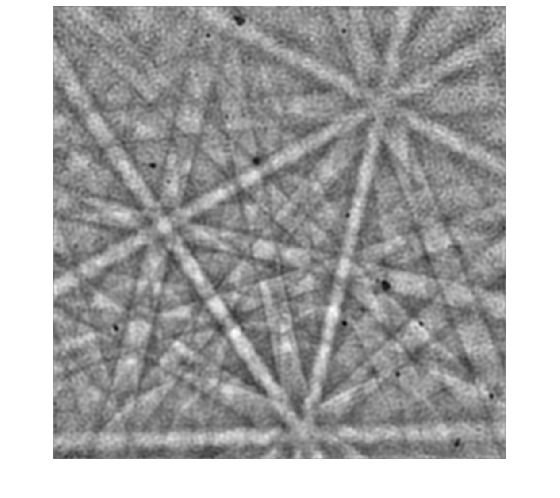

pat.show_pattern

Now we set up a calcf object. The important keyword argument is the` 'AnalysisType'`, the default is 0 for relative analysis (requires a reference pattern), 1 for simulated reference with fixed pattern center, and 2 for simulated reference with pattern center update. We can create this object using the `'initializedCalcF'` method of the mtexHREBSD object. 

Once we have a calcf object we can perform analysis by inputing pattern objects to the `'getBeta' `method. Here we will use real reference and need to declare a reference pattern.

calcf = input.intializeCalcF('AnalysisType', 0);
ref = input.get_pattern(input.refIds);
calcf.getBeta(pat, ref)

ans =   mtexHREBSD_calcF2 with properties:

              ft: [1×1 frameTransformations]
             roi: [1×1 mtexHREBSD_roiSettings]
      assumption: 'free-surface'
    AnalysisType: 0
       RobustFit: 0
    roiCenters_p: [3×48 double]
            qFit: [3×48 double]
               g: [3×3 double]
               q: [3×48 double]
              R2: 0.9905
             SSE: 0.0036
            beta: [3×3 double]


**Full scan analysis**

We will now set up the full analysis using `mtexHREBSDmain` for both strain and dislocation. We first set up a calcf object for strain as input to `mtexHREBSDMain` along with the `mtexHREBSD` object.

calcfstrain = input.intializeCalcF;
output = mtexHREBSDMain(...
    input, ...
    'calcFStrain', calcfstrain...
    );

Then we will use some of the post processing methods included

post = mtexHREBSD_postProcessing(input, output);

Beginning post-processing of HREBSD data...
Getting strains...
Getting stresses...
Complete!


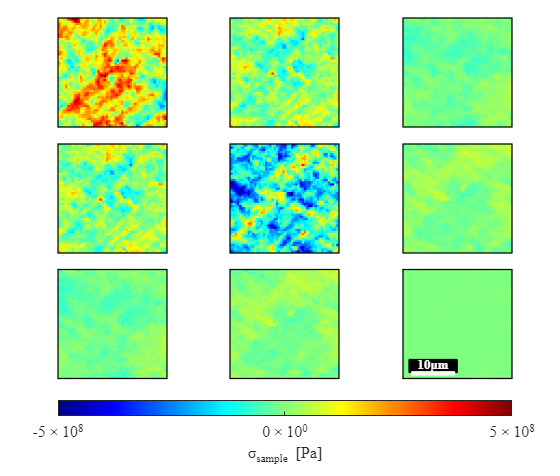

post.get_multiplot('stress', 'refFrame', 'sample', 'clims', [-1,1]*5e8)

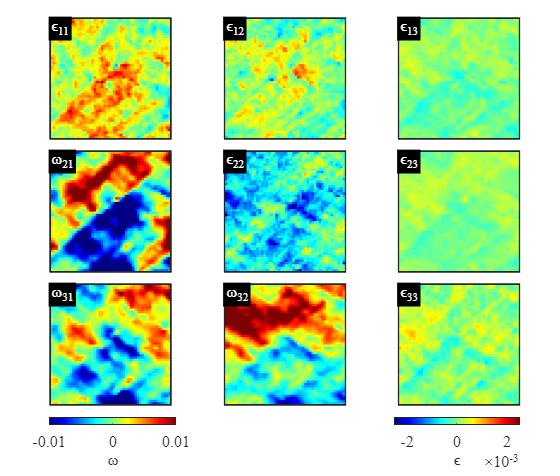

post.multiplotStrainBeta(...
    post, ...
    'climsStrain', [-1,1]*2.5e-3, ...
    'climsBeta', [-1,1]*1e-2, ...
    'refFrame', 'dic', ...
    'doSmooth', 1);

**Parellelization (with parallel computing toolbox)**

By adding the following arguments we can run analysis in parallel. 

`'Autosave'` takes a filename as an input and will periodically save the progress every `'AutosaveInterval'` patterns. If the autosave file already exists the analysis will pick up where it left off.  

`'Verbose'` is a binary argument that can be used to track core utilization

calcfstrain = input.intializeCalcF;
calcfalpha = input.intializeCalcF;
output = mtexHREBSDMain(...
    input, ...
    'calcFStrain', calcfstrain, ...
    'calcFAlpha',calcfalpha, ...
    'ParallelScheme', 2, ...
    'numCores', 10 ...
   );

Elapsed time is 1058.354713 seconds.


Beginning post-processing of HREBSD data...


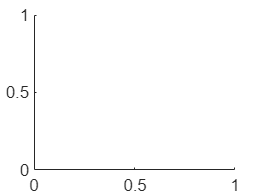

Getting strains...
Getting stresses...
Complete!


post = mtexHREBSD_postProcessing(input, output);

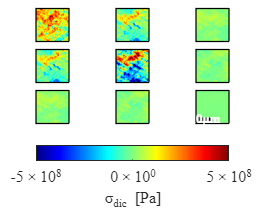

post.get_multiplot('stress', 'refFrame', 'dic', 'clims', [-1,1]*5e8)

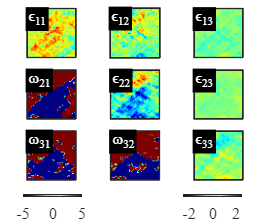

post.multiplotStrainBeta(...
    post, ...
    'climsStrain', [-1,1]*2.5e-3, ...
    'climsBeta', [-1,1]*5e-4, ...
    'refFrame', 'dic', ...
    'doSmooth', 1);

**Pattern center calibration (uses simulated patterns)**

When using simulated references for ansolute strain calculation, it is important to correct the pattern center to avoid error. First we will setup a grid of points to perform this calibration on using the 'get_grid' function and visualize this on a band contrast map

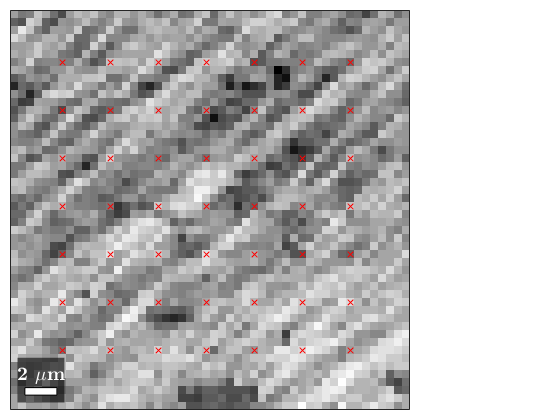

plot(input.ebsd, input.ebsd.prop.bc);
colormap gray
hold on
grid = get_grid(input.ebsd,3);
scatter(input.ebsd.prop.x(grid), input.ebsd.prop.y(grid), 'rx');

Set up and run the pattern center calibration

PCCal = mtexHREBSD_patternCenterCalibration(input,'indicies', grid)

PCCal =   mtexHREBSD_patternCenterCalibration with properties:

    gridIndicies: [49×1 double]
          method: 'F-Delta'
     gridSpacing: 0
       initialPC: []
        actualPC: []
        location: []
     elapsedTime: []


PCCal.get_patternCenterCal(input)

Starting PC Calibration...
Elapsed time is 178.185152 seconds.


ans =   mtexHREBSD_patternCenterCalibration with properties:

    gridIndicies: [49×1 double]
          method: 'F-Delta'
     gridSpacing: 0
       initialPC: [49×3 double]
        actualPC: [49×3 double]
        location: [49×2 double]
     elapsedTime: 178.2163


input.patternCenterOffset = PCCal.get_patternCenterOffset